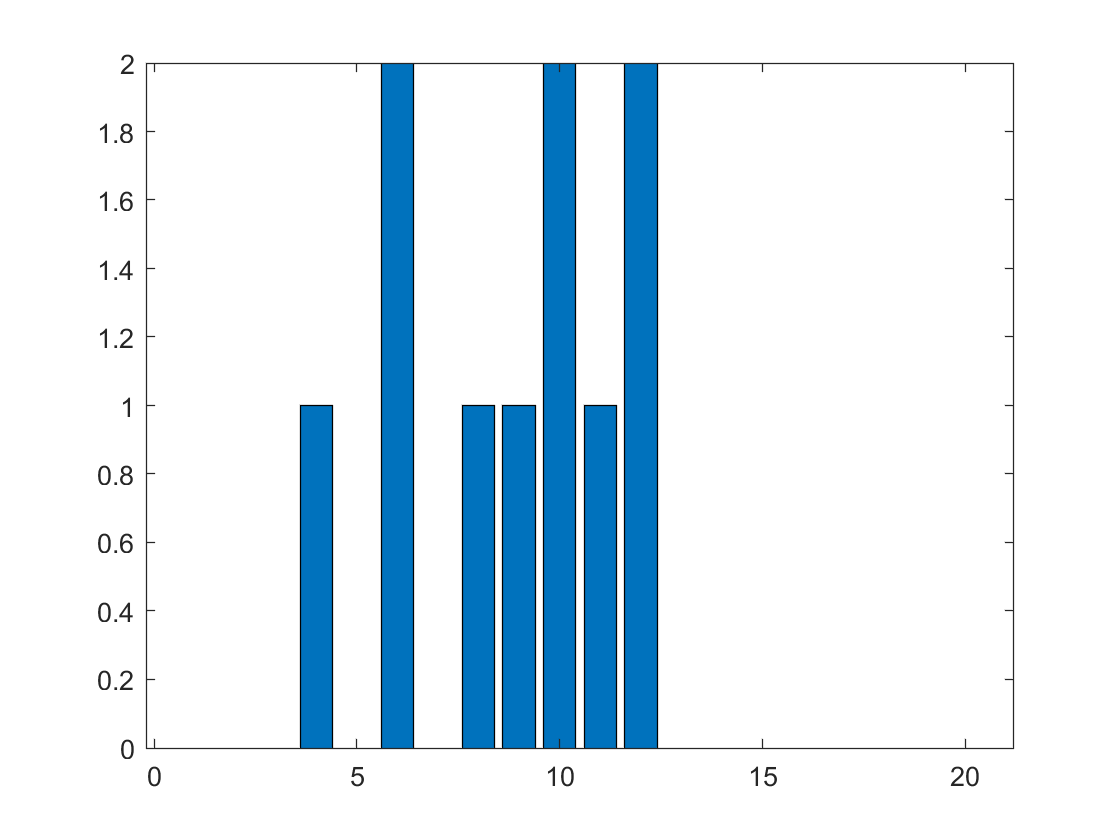

% script plinko
%
% Simple program to simulate the Plinko game. We will neglect the
% boundaries of the board, i.e., we are using a pseudoinfinite board.
% clean up the MATLAB environment

clc
clear all
close all

%start timer
tic

%initialize some parameters
nrows = 15;
nbins = 20;
nballs = 10;
% set up our array for counting the number of balls that end up in each bin
count = zeros(nbins, 1);
% seed random number generator
rng('shuffle');
%loop over the balls
for b = 1:nballs
    %inialize ball position
    x = 1;
    %loop over rows
    for r = 1:nrows
        % randomly move left or right by choosing 0 or 1. use either of the following:        
        %x = x + randi(2) - 1;
        x = x + randi([0,1]);
        
    end
    count(x) = count(x) + 1;

end

% plot a histogram of the counts
% array of bin numbers
% bins = linspace(1,nbins,nbins);
bins = 1:nbins;
bar(bins, count);


%stop timer
toc

Elapsed time is 0.466888 seconds.
